# **SYST 662 Team 1 Project**

## **Questions**

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence? 

(Q2) What fraction of trips are re-routed due to road conditions?

## **Script:**

clear; clc;
tic
rng('default')

% Declare Answer Variables
Q1_predictive_routing_savings_value = " NOT"; % Replace with "" (empty string) if true
Q2_fraction_of_trips_rereouted_value = 0;

% Load Data Files
load EastCoast.mat
load EastCoast_w_supporting_data.mat
load Supporting_Data_Team_01.mat
load trips_short.mat

%% commented out printf's are for debugging

%SIMULATION TASKS
% Develop a simulation (10%) - COMPLETE
% Incorporate random variables for road speed based on provided data (8%)
% Incorporate random variables for road conditions based on provided data (7%)
% Simulating 10 runs, Incorporate a SUFFICIENT and EFFICIENT number of repetitions to generate SIGNIFICANT data (12%)
% Provide Mean and Standard Deviation statistics (8%)

%RESULTS TASKS
% Perform V&V - Overview and Evidence (10%)
% Determine predicitive routing mean savings value (5%)
% Determine predictive routing confidence interval (5%)
% Determine fraction of trips re-routed due to road conditions (10%)
% BEGIN SOLUTION

% Get Trip Data
total_runs = 10;
conf_interval = 0.95;
mins_per_hr = 60;
total_trips = 1;
path_through = 0;
for iter = 700
    path_through = path_through + 1;
    total_trips = iter;
    for run = 1:total_runs
                
        trips = trips_short(total_trips * (run -1) + 1 :(total_trips * run) ,:);
        for o=1:size(trips,1)
            start_name = G.Nodes.Name(trips(o,1));
            end_name   = G.Nodes.Name(trips(o,2));
        end
        
        % Calculate WITHOUT predictive routing:
        G.Edges.Weight = G.Edges.Distance ./ G.Edges.Speed * mins_per_hr;
        sans_t_nominal = zeros(1,size(trips,1) );
        sans_nominal_distance = zeros(1,size(trips,1) );
        sans_average_speed = zeros(1,size(trips,1) );
        for k=1:size(trips,1)  
            [path_nominal , ~] = shortestpath(G,trips(k,1),trips(k,2),'method','positive'); 
            node_ids = findnode(H,path_nominal);
            edge_ids = findedge(H, node_ids(1:end-1), node_ids(2:end));
            sans_t_nominal(k) = sum(H.Edges.Weight(edge_ids)) * mins_per_hr;
            sum_dist = sum(H.Edges.Distance( edge_ids ));
            sans_nominal_distance(k) = sum_dist;
            sans_average_speed(k) = mean(H.Edges.Speed( edge_ids ) );  
        end
        
        % Calculate WITH Predictive Routing:
        with_t_nominal = zeros(1,size(trips,1) );
        with_nominal_distance = zeros(1,size(trips,1) );
        with_average_speed = zeros(1,size(trips,1) );
        save_time_arr = [];
        sans_t_nominal_arr = [];
        for l=1:size(trips,1)  
            [path_nominal , with_t_nominal(l)] = shortestpath(H,trips(l,1),trips(l,2),'method','positive'); 
            node_ids = findnode(H, path_nominal);
            edge_ids = findedge(H, node_ids(1:end-1), node_ids(2:end));
            with_nominal_distance(l) = sum(H.Edges.Distance( edge_ids ) );
            with_average_speed(l) = mean(H.Edges.Speed( edge_ids ) );  
            if sans_nominal_distance(l) > 60
                save_time_arr = [save_time_arr sans_t_nominal(l) - (with_t_nominal(l) * mins_per_hr)];
                sans_t_nominal_arr = [sans_t_nominal_arr sans_t_nominal(l)];
            end
        end
    
        num_rerouted = 0;
        for m=1:size(with_t_nominal,2)
            if sans_nominal_distance(m) ~= with_nominal_distance(m)
               num_rerouted = num_rerouted + 1;
            end
        end
        
        reroute(run) = num_rerouted;
        
        avg_time(run) = mean(sans_t_nominal);
        var_time(run) = var(sans_t_nominal);
        avg_percentage_time_saved(run) = mean(save_time_arr ./ sans_t_nominal_arr)*100;
    
    end
    
    %time saved in mins interval, not percentage saved
    Q2_fraction_of_trips_rereouted_value = sum(reroute)/(total_trips*total_runs);
    
    
    alpha = 1- conf_interval;
    tstat = tinv(1-alpha/2,total_runs-1);
    runsbar = mean(avg_percentage_time_saved);
    S2 = var(avg_percentage_time_saved);
    pmu = runsbar + tstat*sqrt(S2/total_runs);
    mmu = runsbar - tstat*sqrt(S2/total_runs);
    fprintf('Confidence Interval = [%6.2f, %6.2f]\n', mmu, pmu);
    fprintf('Average Percentage Time Saved = %6.2f\n', runsbar);
    fprintf('STD of Average Percentage Time Saved = %6.2f\n', S2);
    if 5 > mmu && 5 < pmu
        Q1_predictive_routing_savings_value = '';
    end
end

Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700
Trips taken for this Repetition: 700


Confidence Interval = [  1.50,   3.18]


Average Percentage Time Saved =   2.34


STD of Average Percentage Time Saved =   1.39


## **Result:**

% Output answers to Q1 and Q2
fprintf('(Q1) On average, does predictive routing save more than 5%% of the trip time to a 95%% confidence?');

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence?

fprintf('\tQ1: On average, predictive routing does%s save more than 5%% of the trip time to a 95%% confidence.', Q1_predictive_routing_savings_value);

	Q1: On average, predictive routing does NOT save more than 5% of the trip time to a 95% confidence.

fprintf('(Q2) What fraction of trips are re-routed due to road conditions?');

(Q2) What fraction of trips are re-routed due to road conditions?

fprintf('\tQ2: %0.4f%% of trips are re-routed due to road conditions.\n\n', Q2_fraction_of_trips_rereouted_value*100);

	Q2: 6.3571% of trips are re-routed due to road conditions.



## Unit Testing

fprintf('The following output contains results from the Verification and Validation Plan.');

The following output contains results from the Verification and Validation Plan.

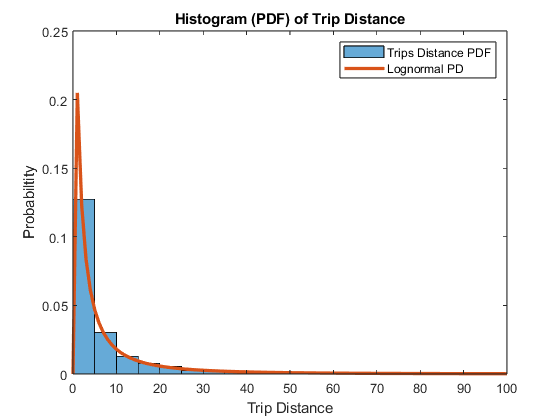

pd = fitdist(trips_short(:,3)/100, 'Lognormal');

% running chi^2 test, K-S test, and A-D test against lognormal distribution
[h1,p1,st] = chi2gof(trips_short(:,3)/100, 'CDF', pd, 'Alpha', alpha); % h = 0, PASS
[h2,p2,ksstat,cv] = kstest(trips_short(:,3)/100, 'CDF', pd, 'Alpha', alpha); % h = 0, PASS
[h3,p3,adstat,cv] = adtest(trips_short(:,3)/100, 'Distribution', pd, 'Alpha', alpha); % h = 0, PASS

% Plot histogram normalized to PDF of trips data
figure(1);
histogram(trips_short(:,3)/100, 'Normalization', 'PDF');
xlim([0,100]);
title('Histogram (PDF) of Trip Distance');
xlabel('Trip Distance'); 
ylabel('Probabiltity');
hold on
x = 0:100;
y = pdf(pd,x);
plot(x,y,'LineWidth',2.5)
legend('Trips Distance PDF','Lognormal PD');
hold off

fprintf("Input data Mu: %f",pd.mu)

Input data Mu: 1.014351

fprintf("Input data Sigma: %f",pd.sigma)

Input data Sigma: 1.587322

toc

Elapsed time is 5.751222 seconds.
